# RVC 1, Ch 2

clear variables
close all
clc
clear livescript

## Lec 01.6 (Ch 2.1) 2D rotations

Let's create a 2D rotation matrix about some angle:

R = rot2(0)

Let's try a 0.2 radian rotation:

R=rot2(0.2)

Rotations, can also be defined in degrees. Let's try a 30 degree rotation:

R=rot2(30,'deg')

### Rotation Matrtix Properties

Rotation matrices are :

- orthnormal: columns are orthogonal to each other and unit length

- full rank:     independent/invertible

- symmetrical: the inverse is equal to the transpose

Let's check them out. 

#### A. Orthonormal

Orthonormal vectors both have a norm of 1 and are perpendicular to each other. 

If we take the dot product of two perpendicular vectors, the result should be 0.

% Extract two columns:
c1=R(:,1)
c2=R(:,2)

Compute their norms:

norm(c1)
norm(c2)

Now, let's take their dot products:

dot(c1,c2)

**B. Full Rank**

Full rank matrices means that no column or row in the matrix is a linear combination of any other column or row and so it can reach the full space of the dimensionality of the matrix. 

Currently in two dimensions, the rank of the rotation matrix should be 2. 

% Full rank
rank(R)

If a matrix is full rank, it's determinant will never be zero. 

#### Determinant

If the determinant is zero, the matrix would be singular (it would have dependencies) and it would not be able to span the full space.

det(R)

#### Invertible

Full rank matrices (those with non zero determinants) can always be inverted. 

Inverted rotation matrices are inverse rotations. 

If R is associated with a 30 degree rotation, then inv(R) will be a -30 degree rotation.

inv(R)

Let's compare if we directly form a -30 degree rotation:

rot2(-30,'deg')

### C. Symmetrical Matrices

The last property of rotaion matrices is that they are symmetrical. 

Symmetrical matrices have their inverses equal to their transpose. 

% Transpose
R'

Let's compare with the inv(R):

inv(R)

#### Compounded Rotations (Chains of Rotation Matrices)

Chains of rotation matrices keep the same properties:

det(R*R)

#### Plotting

% Plot coordinate axis by this rotation wrt origin
grid on,
trplot2(R)
axis equal

#### Symbolic Notation

Note, that matlab also easily allow us to work with symoblic notation by using the ***syms*** function.

syms theta
R = rot2(theta)

Compounded rotations are also possible:

R*R

Complex expressions can sometimes be simplified with the function **simplify**:

simplify(R*R)

Symbolic expressions for the determinant are also obtained:

det(R)
simplify(det(R))

## Lec 01.7 (Ch 2.1) 2D Rotation and Translation

In this section we will learn to create translations, along with a combinations of translations and rotations (i.e. a homogeneous transform).

We will also learn to distinguish between manual operations and the use of the SE2 class. 

### Homogeneous Transformations

Create a homogenous transformation representation a pure translation:

T0 = transl2(1, 2)

T0 =      1     0     1
     0     1     2
     0     0     1


Create a homogenous transformation representation a pure rotation of 30 degrees in radians or degrees:

R0=trot2(0.5236) % 30 degree rotation

R0 =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


R0=trot2(30,'deg')

R0 =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


Let us now combine a 2D homogenous tranformation matrix with a rotation and translation.

We will explore two methods to do this:

- Manual method

- SE object

#### 1. Manual Homogeneous Tranformation Instantiation:

W_T = transl2(1, 2) * trot2(30, 'deg')

W_T =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


#### 2. Special Euclidean (SE2) Group

The idea from groups comes from Group Thoery. An important aspect in abstract algebra.

If you want to learn more about groups check out the following [video](https://www.youtube.com/watch?v=KufsL2VgELo&list=PLts2VQxwm4syWiLA7P-_DREHDV3OyP14w&index=1&t=855s).

But put simply, it will be an object that allows us to encode rotations and translations. 

Note that SE2 command is a class and when used it will instantiate an object of that class. 

Let's create a homogeneous transformation that involves a translation of [1,2] and a 30 degree rotation in the 2D plane. 

This could be the pose of the camera wrt to the world: W_T_C

W_T_C=SE2(1,2,30,'deg') % in degrees

 

W_T_C = 
    0.8660   -0.5000         1
    0.5000    0.8660         2
         0         0         1


W_T_C=SE2(1,2,0.5236)   % in radians

 

W_T_C = 
    0.8660   -0.5000         1
    0.5000    0.8660         2
         0         0         1


Note that this is not a regular matrix but an SE2 object

class(W_T_C)

ans = 'SE2'

You can learn of all the methods available to an SE2 object by calling help:

help SE2

 SE2 Representation of 2D rigid-body motion
 
  This subclasss of RTBPose is an object that represents rigid-body motion in 2D. 
  Internally this is a 3x3 homogeneous transformation matrix (3x3) belonging to 
  the group SE(2).
 
  Constructor methods::
   SE2          general constructor
   SE2.exp      exponentiate an se(2) matrix  
   SE2.rand     random transformation
   new          new SE2 object
 
  Display and print methods::
   animate          ^graphically animate coordinate frame for pose
   display          ^print the pose in human readable matrix form
   plot             ^graphically display coordinate frame for pose
   print            ^print the pose in single line format
 
  Group operations::
   *            ^mtimes: multiplication (group operator, transform point)
   /            ^mrdivide: multiply by inverse
   ^            ^mpower: exponentiate (integer only): 
   inv          inv

You can extract only the rotation matrix:

W_T_C.R

ans =     0.8660   -0.5000
    0.5000    0.8660


You can extract the angle of the rotation:

W_T_C.angle

ans = 0.5236

You can extract the translation:

W_T_C.t

ans =      1
     2


You can extract the homogeneous transformation as a matrix of doubles:

W_T_C.T

ans =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


class(W_T_C.T)

ans = 'double'

You can plot the transformation:

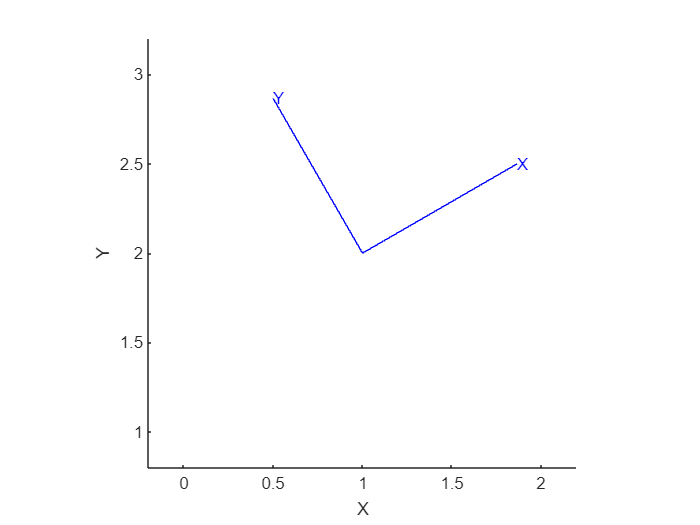

W_T_C.plot

Better yet, you can animate the transformation from the original frame to the current frame (best run in the command window):

W_T_C.animate

If you do not have an SE2 object, you can still plot a regular homogeneous transformation using the **trplot2 **method:

W_T_C = transl2(1, 2)

W_T_C =      1     0     1
     0     1     2
     0     0     1


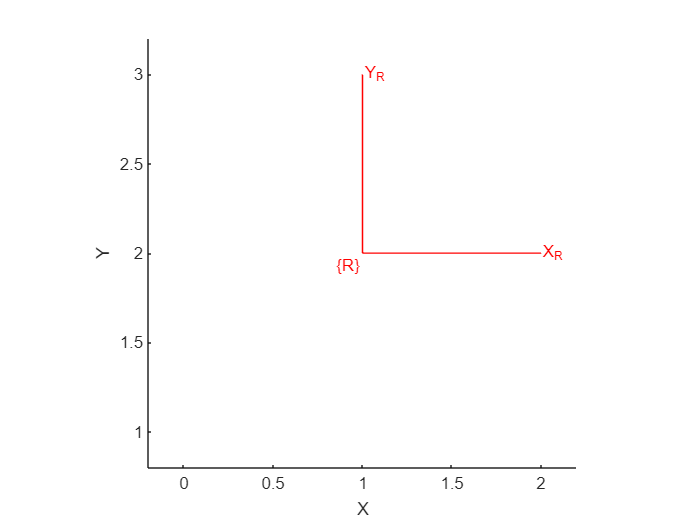

trplot2(W_T_C, 'frame', 'W', 'color', 'b') % frame name: 1, color: b

*Note: properties usually come in pairs: 'property_name', 'property_value'*

You can adjust the axis with either of the following commands:

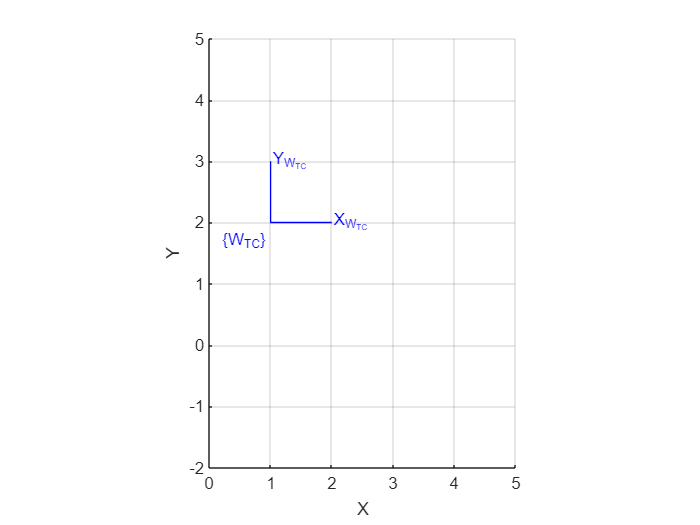

plotvol( [0 5 -2 5] );                    % Set the axes to specific limits. Can also try: axis square
trplot2(W_T_C, 'frame', 'W_T_C', 'color', 'b') % frame name: 1, color: b

### Compound Pose Transformations

Consider a 2nd pose. One that identifies the robot wrt to the world: W_T_R

W_T_R = transl2(2, 1)

W_T_R =      1     0     2
     0     1     1
     0     0     1


Visualize:

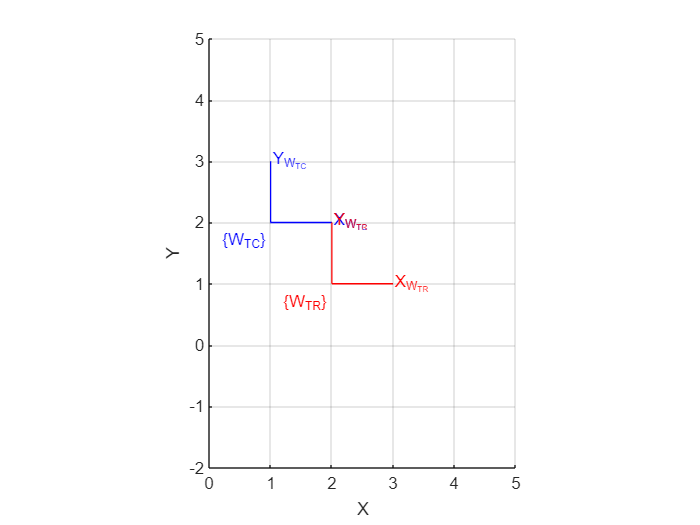

trplot2(W_T_R, 'frame', 'W_T_R', 'color', 'r');

What if we want to get the robot pose wrt to the camera: C_T_R

To get there we need the operation: C_T_R = C_T_W*W_T_R

This will requires us to compute the inverse of W_T_C

C_T_R = inv(W_T_C)*W_T_R

C_T_R =      1     0     1
     0     1    -1
     0     0     1


### Transforming Vectors

Let us now consider situations where we have some point P (imagine the center of mass of a target object).

Its coordinates are wrt to a certain frame of reference (say the camera of the robot), but you want to transform the vector wrt to the world frame that is used by the robot arm to direct it to grasp the object.

% Create a point P that is [3,2] wrt to the camera world frame
C_P = [3;2;1] % Homogeneous coordinate

C_P =      3
     2
     1


To plot it appropriately, we need to compute P wrt to the world: W_P = W_T_C*C_P

C_P = W_T_C*C_P

C_P =      4
     4
     1


To plot the points, extract the first two coordiantes:

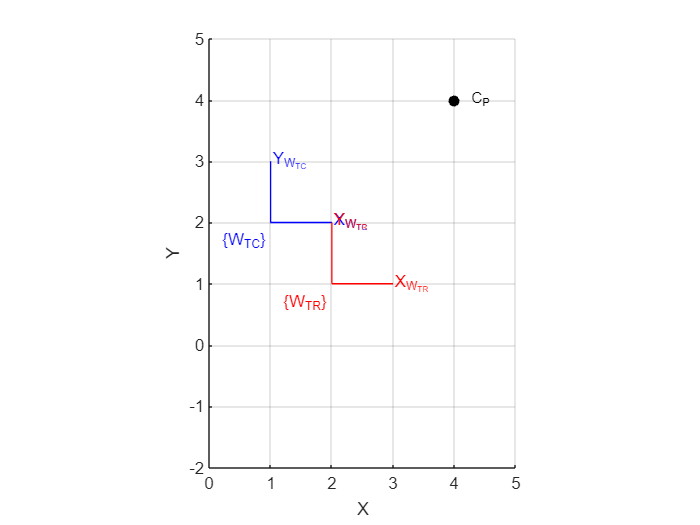

plot_point(C_P(1:2), 'label', ' C_P', 'textcolor', 'k', 'solid', 'ko')

What might C_P = [3,2] be wrt to the robot `R_P`:

- Get the transformation of the camera wrt to the world `R_T_C`. 

- Compute `W_P` as follows: `R_P = R_T_C * C_P`

- But to get `R_T_C` we will `R_T_W*W_T_C`

% Get R_T_W
R_T_C = inv(W_T_R)*W_T_C % Note that the inv of a homogenous transformation matrix is not equal to its transpose (not an orthonormal rotation matrix).

R_T_C =      1     0    -1
     0     1     1
     0     0     1


Let's do one more coordinate transform. This time from the camera coordinate system to the robot coordinate system. 

Coinsider the original coordinates of our target object with respect to the camera frame C_P = [3,2]. 

What if we wanted to transform it in terms of the robot coordinate frame?

We would need: R_P = R_T_C * C_P 

What coordinate would you expect to get? [2,3]? Do we get it?

R_P = R_T_C*[3;2;1]

R_P =      2
     3
     1
